# F25 Eksamen

%% 62743 Digital Signal Processing - F25 Eksamen
% Danmarks Tekniske Universitet
% Dato: 10/12 2025
clear; clc; close all;
addpath('C:\Users\Mads2\DTU\3.semester\DSP\Helpers\');
%% Global image directory (Obsidian path)
imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end

## EKSAMENSOPGAVE 1 (25%)

%  LTI System Analysis

% Givne signaler og data
% Input signals
% x1[n] = δ[n] - 2δ[n-1]
% x2[n] = -δ[n] + 3δ[n-1]

x1 = [1, -2];       % x1[n] coefficients: [x1(0), x1(1)]
x2 = [-1, 3];       % x2[n] coefficients: [x2(0), x2(1)]

% Output signals (from table)
n_vals = 0:5;
y1 = [1, 0, 2, -10, -3, -2];    % y1[n] for n = 0,1,2,3,4,5
y2 = [-1, 1, 0, 16, 5, 3];      % y2[n] for n = 0,1,2,3,4,5


## Spørgsmål 1-1: Beregn x1[n] + x2[n]

% Step 1: Write signals with explicit coefficients
% x1[n] = (+1)·δ[n] + (-2)·δ[n-1]
% x2[n] = (-1)·δ[n] + (+3)·δ[n-1]

% Combining terms
% δ[n]:   1 + (-1) = 0
% δ[n-1]: -2 + 3 = 1

% Result: δ[n-1] 

fprintf('Result: x₁[n] + x₂[n] = δ[n-1]\n');

Result: x₁[n] + x₂[n] = δ[n-1]


## Spørgsmål 1-2a: Beregn y1[n] + y2[n]

y_sum = y1 + y2;
disp('y1 + y2 ='); disp(y_sum);

y1 + y2 =
     0     1     2     6     2     1




%so
%y1[n] + y2[n] = δ[n-1]+2δ[n-2]+6δ[n-3]+2δ[n-4]+δ[n-5]

fprintf('Result: y1[n] + y2[n] = δ[n-1]+2δ[n-2]+6δ[n-3]+2δ[n-4]+δ[n-5] \n');

Result: y1[n] + y2[n] = δ[n-1]+2δ[n-2]+6δ[n-3]+2δ[n-4]+δ[n-5] 


## Spørgsmål 1-2b: Eftervis at h[n] = δ[n] + 2δ[n-1] + 6δ[n-2] + 2δ[n-3] + δ[n-4]

% We know from 1-1 that input was x1 + x2 = δ[n-1]
% So the output y1 + y2 is the impulse response delayed by 1: h[n-1]

% y1 + y2 = 0·δ[n] + 1·δ[n-1] + 2·δ[n-2] + 6·δ[n-3] + 2·δ[n-4] + 1·δ[n-5]
% This equals h[n-1]

% To get h[n], we shift everything left by 1 (replace n-1 with n):
% term δ[n-1] becomes δ[n]
% term δ[n-2] becomes δ[n-1]
% ... and so on

% Resulting h[n]:
fprintf('Result: h[n] = δ[n] + 2δ[n-1] + 6δ[n-2] + 2δ[n-3] + δ[n-4] \n');

Result: h[n] = δ[n] + 2δ[n-1] + 6δ[n-2] + 2δ[n-3] + δ[n-4] 


## Spørgsmål 1-3a: Angiv systemfunktionen H(z)

%% Spørgsmål 1-3a: Angiv systemfunktionen H(z)
% h[n] = δ[n] + 2δ[n-1] + 6δ[n-2] + 2δ[n-3] + δ[n-4]
% 
% Taking Z-transform (using δ[n-k] → z^(-k)):
%   δ[n]   → 1
%   2δ[n-1] → 2z^(-1)
%   6δ[n-2] → 6z^(-2)
%   2δ[n-3] → 2z^(-3)
%   δ[n-4] → z^(-4)

% Manual result:
fprintf('Result: H(z) = 1 + 2z^(-1) + 6z^(-2) + 2z^(-3) + z^(-4)\n\n');

Result: H(z) = 1 + 2z^(-1) + 6z^(-2) + 2z^(-3) + z^(-4)



## Spørgsmål 1-3b: Angiv frekvensresponset H(ω) = H(z)|_{z=e^{jω}}

% H(z) = 1 + 2z^(-1) + 6z^(-2) + 2z^(-3) + z^(-4)
%substitute z=e^(jω) to get frekvensrespons

% H(ω)= 1 + 2e^(-jω) + 6e^(-2jω) + 2e^(-3jω) + e^(-4jω)


% Manual result:
fprintf('Result: H(ω)= 1 + 2e^(-jω) + 6e^(-2jω) + 2e^(-3jω) + e^(-4jω)\n\n');

Result: H(ω)= 1 + 2e^(-jω) + 6e^(-2jω) + 2e^(-3jω) + e^(-4jω)



## Spørgsmål 1-4a: Beregn |H(ω)| og ∠H(ω) analytisk

% Given: H(ω) = 1 + 2e^(-jω) + 6e^(-2jω) + 2e^(-3jω) + e^(-4jω)
%
% Step 1: Factor out center phase term e^(-j2ω)
%   H(ω) = e^(-j2ω) (e^(j2ω) + 2e^(jω) + 6 + 2e^(-jω) + e^(-j2ω))
%
% Step 2: Group symmetric terms
%   H(ω) = e^(-j2ω) [(e^(j2ω) + e^(-j2ω)) + 2(e^(jω) + e^(-jω)) + 6]
%
% Step 3: Apply Euler's identity: e^(jθ) + e^(-jθ) = 2cos(θ)
%   H(ω) = e^(-j2ω) [2cos(2ω) + 4cos(ω) + 6]
%
% Step 4: Extract magnitude and phase
%   Since H(ω) = e^(-j2ω) · A(ω) where A(ω) is real:
%   |H(ω)| = |A(ω)| and ∠H(ω) = -2ω

fprintf('Magnitude response:\n');

Magnitude response:


fprintf('|H(ω)| = 2cos(2ω) + 4cos(ω) + 6\n\n');

|H(ω)| = 2cos(2ω) + 4cos(ω) + 6




fprintf('Phase response:\n');

Phase response:


fprintf('∠H(ω) = -2ω\n\n');

∠H(ω) = -2ω



##  Spørgsmål 1-4b: Plot |H(ω)| og ∠H(ω) for -π ≤ ω ≤ π

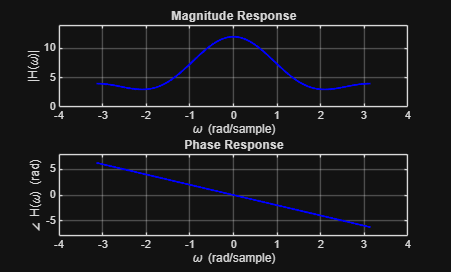

% Frequency vector
omega = linspace(-pi, pi, 1024);

% Analytical formulas from 1-4a
mag = 2*cos(2*omega) + 4*cos(omega) + 6;
phase = -2*omega;

% Create plots
figure;

% Magnitude Response
subplot(2,1,1);
plot(omega, mag, 'b-', 'LineWidth', 1.5);
xlabel('\omega (rad/sample)');
ylabel('|H(\omega)|');
title('Magnitude Response');
ylim ([0 14]);
grid on;

% Phase Response
subplot(2,1,2);
plot(omega, phase, 'b-', 'LineWidth', 1.5);
xlabel('\omega (rad/sample)');
ylabel('\angle H(\omega) (rad)');
title('Phase Response');
ylim ([-8 8]);
xlim ([-4 4]);
grid on;

% Export figure
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F25_1_4b_MagPhase.png'), 'Resolution', 300);

## Spørgsmål 1-5: Find systemfunktion for samlet system (T1, T2, T3)

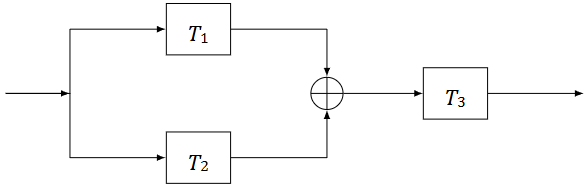

% Given systems
H1_B = [1, 2, 6, 2, 1];      % From problem 1-3
H2_B = [3, -10, -11];         % Given
H3_A = [1, 0, -1/4];          % Denominator of H3


## Step 1: Add parallel systems (T1 + T2)

%T1 + T2
% (1+3) (2+(-10)) (6+(-11)) 2 1
H_parallel_B = [4, -8, -5, 2, 1];  % Add coefficients

fprintf('H1(z) + H2(z) = 4 - 8z^(-1) - 5z^(-2) + 2z^(-3) + z^(-4)\n\n');

H1(z) + H2(z) = 4 - 8z^(-1) - 5z^(-2) + 2z^(-3) + z^(-4)




%% Step 2: Divide by H3 denominator to cancel factors
% Use polynomial division (positive powers)
num = [4, -8, -5, 2, 1];      % 4z^4 - 8z^3 - 5z^2 + 2z + 1
den = [1, 0, -1/4];            % z^2 - 1/4

[H_total_B, remainder] = deconv(num, den)

H_total_B =      4    -8    -4


remainder =      0     0     0     0     0



fprintf('After polynomial division:\n');

After polynomial division:


fprintf('H_total(z) = 4 - 8z^(-1) - 4z^(-2)\n\n');

H_total(z) = 4 - 8z^(-1) - 4z^(-2)




%% Step 3: Show it's FIR
fprintf('=== FIR Verification ===\n');

=== FIR Verification ===


fprintf('Coefficients: [%g, %g, %g]\n', H_total_B);

Coefficients: [4, -8, -4]


fprintf('Denominator = 1 → FIR system ✓\n');

Denominator = 1 → FIR system ✓


fprintf('Impulse response: h4[n] = 4δ[n] - 8δ[n-1] - 4δ[n-2]\n');

Impulse response: h4[n] = 4δ[n] - 8δ[n-1] - 4δ[n-2]


## EKSAMENSOPGAVE 2 (25%)

## IIR Butterworth Highpass Filter Design (BLT)

% Givne specifikationer
Fs = 4000;              % Sampling frequency [Hz]
Ts = 1/Fs;              % Sampling period [s]

fs_hz = 450;            % Stopband edge frequency [Hz]
fp_hz = 1000;           % Passband edge frequency [Hz]

As_dB = 30;             % Stopband attenuation [dB]
Ap_dB = 3;              % Passband attenuation [dB]

% Normalized digital frequencies
omega_s = 2*pi*fs_hz/Fs;    % Stopband [rad/sample]
omega_p = 2*pi*fp_hz/Fs;    % Passband [rad/sample]


## Spørgsmål 2-1: Analog prototype Butterworth filter

% (1) Beregn epsilon (ε)

epsilon = sqrt(10^(Ap_dB/10) - 1);
fprintf('ε = %.2f\n\n', epsilon);

ε = 1.00





% (2) Beregn digitale vinkelfrekvenser (ω)
fprintf('Digital frequencies:\n');

Digital frequencies:


fprintf('ω_s = %.4f rad/sample = %.4fπ\n', omega_s, omega_s/pi);

ω_s = 0.7069 rad/sample = 0.2250π


fprintf('ω_p = %.4f rad/sample = %.4fπ\n\n', omega_p, omega_p/pi);

ω_p = 1.5708 rad/sample = 0.5000π




% Pre-warping: Digital → Analog
Omega_s = 2*Fs * tan(omega_s/2);
Omega_p = 2*Fs * tan(omega_p/2);

fprintf('Pre-warped analog frequencies:\n');

Pre-warped analog frequencies:


fprintf('Ω_s = %.2f rad/s\n', Omega_s);

Ω_s = 2951.36 rad/s


fprintf('Ω_p = %.2f rad/s\n\n', Omega_p);

Ω_p = 8000.00 rad/s




% (3) Beregn minimum filter orden n
% For HIGHPASS: ratio = Omega_p / Omega_s (inverted!)
ratio = Omega_p / Omega_s;

% Butterworth order formula
n_exact = log10((10^(As_dB/10) - 1) / (10^(Ap_dB/10) - 1)) / (2*log10(ratio));
n = ceil(n_exact);

fprintf('Filter order calculation:\n');

Filter order calculation:


fprintf('Ratio (Ω_p/Ω_s) = %.4f\n', ratio);

Ratio (Ω_p/Ω_s) = 2.7106


fprintf('n_exact = %.4f\n', n_exact);

n_exact = 3.4655


fprintf('n_min = %d\n\n', n);

n_min = 4





% (4) Opskriv prototype lavpas transferfunktion (se appendix)
B_proto = 1;
A_proto = [1, 2.6131, 3.4142, 2.6131, 1];



% Create transfer function object
fprintf('Prototype Butterworth lowpass transfer function H_LP(s):\n');

Prototype Butterworth lowpass transfer function H_LP(s):


H_proto = tf(B_proto, A_proto)


H_proto =
 
                      1
  -----------------------------------------
  s^4 + 2.613 s^3 + 3.414 s^2 + 2.613 s + 1
 
Continuous-time transfer function.


## Spørgsmål 2-2: LP → HP transformation

% (a) Transformation formula
fprintf('(a) Transformation formula: s → Ω_p/s\n');

(a) Transformation formula: s → Ω_p/s


fprintf('    Where Ω_p = %.2f rad/s\n\n', Omega_p);

    Where Ω_p = 8000.00 rad/s




% (b) Apply LP to HP transformation
fprintf('(b) Analog Highpass Filter H_HP(s):\n');

(b) Analog Highpass Filter H_HP(s):



% Use MATLAB's lp2hp function
[B_hp, A_hp] = lp2hp(B_proto, A_proto, Omega_p);

% Display transfer function
H_hp = tf(B_hp, A_hp)


H_hp =
 
     s^4 + 5.773e-12 s^3 + 4.719e-09 s^2 + 0.0003625 s
  --------------------------------------------------------
  s^4 + 2.09e04 s^3 + 2.185e08 s^2 + 1.338e12 s + 4.096e15
 
Continuous-time transfer function.



% (c) Plot analog magnitude response
fprintf('\n(c) Plotting analog magnitude response...\n');


(c) Plotting analog magnitude response...


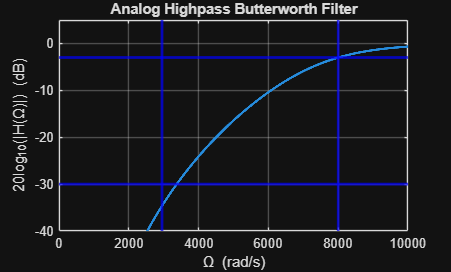


Omega = [0:1:1E4];  % 0 to 10 krad/s (match official solution)
H_analog = freqs(B_hp, A_hp, Omega);

figure;
plot(Omega, 20*log10(abs(H_analog)), 'LineWidth', 2);
hold on;

% Add specification lines (blue lines like official solution)
xline(Omega_s, 'b-', 'LineWidth', 2);  % Stopband edge
xline(Omega_p, 'b-', 'LineWidth', 2);  % Passband edge
yline(-30, 'b-', 'LineWidth', 2);      % Stopband requirement
yline(-3, 'b-', 'LineWidth', 2);       % Passband requirement

xlabel('\Omega (rad/s)');
ylabel('20log_{10}(|H(\Omega)|) (dB)');
title('Analog Highpass Butterworth Filter');
grid on;
xlim([0 10000]);
ylim([-40 5]);

hold off;

% Export figure
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F25_2_2_AnalogHP_Magnitude.png'), 'Resolution', 300);


% (d) Visual verification
fprintf('\n(d) Verification:\n');


(d) Verification:


fprintf('De blå linjer på plottet indikerer kravspecifikationerne for det analoge filter.\n');

De blå linjer på plottet indikerer kravspecifikationerne for det analoge filter.


fprintf('Filteret opfylder de analoge design krav.\n');

Filteret opfylder de analoge design krav.


## Spørgsmål 2-3: Bilinear transformation (BLT)

% (a) BLT relation
alpha = 2/Ts;
fprintf('(a) BLT parameter α = 2/T_s = 2·F_s = %.0f\n', alpha);

(a) BLT parameter α = 2/T_s = 2·F_s = 8000


fprintf('    Transformation: s = α·(z-1)/(z+1)\n\n');

    Transformation: s = α·(z-1)/(z+1)




% (b) Apply Bilinear Transform
fprintf('(b) Digital Highpass Filter H_HP(z):\n');

(b) Digital Highpass Filter H_HP(z):



% Use MATLAB's bilinear function
[Bz, Az] = bilinear(B_hp, A_hp, Fs);


% Normalize so a[0] = 1 (should already be, but good practice)
Bz = Bz / Az(1);
Az = Az / Az(1);

% Display transfer function
H_digital = tf(Bz, Az, Ts, 'Variable', 'z^-1')


H_digital =
 
  0.09398 - 0.3759 z^-1 + 0.5639 z^-2 - 0.3759 z^-3 + 0.09398 z^-4
  ----------------------------------------------------------------
  1 + 3.903e-16 z^-1 + 0.486 z^-2 + 3.662e-16 z^-3 + 0.01767 z^-4
 
Sample time: 0.00025 seconds
Discrete-time transfer function.


## Spørgsmål 2-4: Verificer digital filter

% (a) Plot magnitude response in dB vs frequency (Hz)
fprintf('(a) Plotting digital magnitude response...\n');

(a) Plotting digital magnitude response...


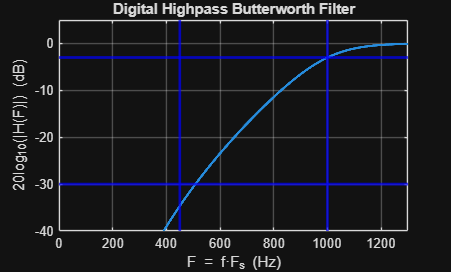


[H, f] = freqz(Bz, Az, 1E4, Fs);  % Match official solution

figure;
plot(f, 20*log10(abs(H)), 'LineWidth', 2);
hold on;

% Add specification lines (blue lines like official solution)
xline(fs_hz, 'b-', 'LineWidth', 2);  % Stopband edge at 450 Hz
xline(fp_hz, 'b-', 'LineWidth', 2);  % Passband edge at 1000 Hz
yline(-30, 'b-', 'LineWidth', 2);    % Stopband requirement
yline(-3, 'b-', 'LineWidth', 2);     % Passband requirement

xlabel('F = f·F_s (Hz)');
ylabel('20log_{10}(|H(F)|) (dB)');
title('Digital Highpass Butterworth Filter');
grid on;
xlim([0 1300]);  % Match official solution range
ylim([-40 5]);

hold off;

% Export figure
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F25_2_4_DigitalHP_Magnitude.png'), 'Resolution', 300);


% (b) Visual verification from plot
fprintf('\n(b) De blå linjer på plottet indikerer de digitale filter kravspecifikationerne\n');


(b) De blå linjer på plottet indikerer de digitale filter kravspecifikationerne



fprintf('(c) Aflæste værdier på plottet:\n');

(c) Aflæste værdier på plottet:


fprintf('    At 450 Hz: ≈ -34.6 dB (requirement: ≤ -30 dB) ✓\n');

    At 450 Hz: ≈ -34.6 dB (requirement: ≤ -30 dB) ✓


fprintf('    At 1000 Hz: ≈ -3.0 dB (requirement: ≥ -3 dB) ✓\n\n');

    At 1000 Hz: ≈ -3.0 dB (requirement: ≥ -3 dB) ✓




fprintf('Filteret opfylder kravspecifikationerne.\n');

Filteret opfylder kravspecifikationerne.


## EKSAMENSOPGAVE 3 (25%)

## EKSAMENSOPGAVE 3: Sampling, Aliasing, and Inverse Systems

% Given parameters
F1 = 1500; A1 = 3;
F2 = 4200; A2 = 2;
Fs = 8000;


## Problem 3-1: Full Spectrum

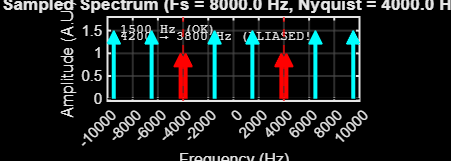

F1=1500; A1=3; F2=4200; A2=2; Fs=8000;
F2_alias = Fs-F2;

% Build replicas
freqs=[]; amps=[]; colors={};
for k=-1:1
    freqs=[freqs, F1+k*Fs, -F1+k*Fs, F2_alias+k*Fs, -F2_alias+k*Fs];
    amps=[amps, A1/2, A1/2, A2/2, A2/2];
    colors=[colors, 'c','c','r','r'];
end

% Plot with LARGER figure size
plot_spectrum(freqs, amps, 'Colors', colors, 'Fs', Fs, ...
    'LegendLabels', {'1500 Hz (OK)', '4200 → 3800 Hz (ALIASED!'}, ...
    'XRange', [-10000,10000], 'XStep', 2000);

% Make figure WIDER
set(gcf, 'Position', [100, 100, 1400, 500]);  % [x, y, width, height]

xline([Fs/2, -Fs/2], '--r', 'LineWidth', 1.5);

% Export with HIGH resolution
exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_3_1_Spectrum.png'), ...
               'Resolution', 300);  % 300 DPI = high quality

## Problem 3-2: Aliasing?

% Answer: Look at plot above - red arrows show aliased component at 3800 Hz


## Problem 3-3: Filter Pole-Zero Diagrams

% From difference equation: y[n] - 0.7y[n-1] + 0.1y[n-2] = x[n] + x[n-1]

% Numerator coefficients (x terms, right side)
B = [1, 1];  % Corresponds to: x[n] + x[n-1]

% Denominator coefficients (y terms, left side)
A = [1, -0.7, 0.1];  % Corresponds to: y[n] - 0.7y[n-1] + 0.1y[n-2]

% Display transfer function
fprintf('H1(z) Transfer Function:\n');

H1(z) Transfer Function:


H1 = tf(B, A, -1)  % -1 = discrete, unspecified sample time


H1 =
 
        z + 1
  -----------------
  z^2 - 0.7 z + 0.1
 
Sample time: unspecified
Discrete-time transfer function.


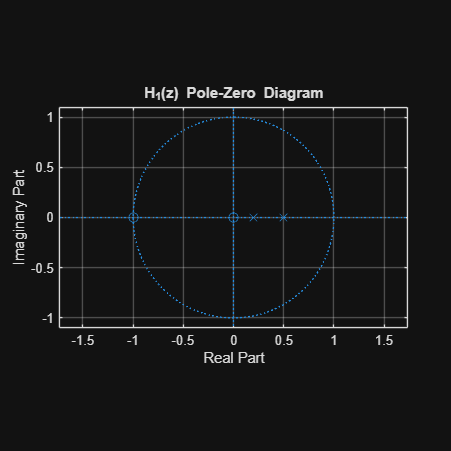


% H1(z) pole-zero plot
figure;
zplane(B, A);
title('H_1(z) Pole-Zero Diagram');
grid on;
set(gcf, 'Position', [100, 100, 800, 800]);
exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_3_3_H1.png'), 'Resolution', 300);


% Inverse system
fprintf('\nH2(z) = 1/H1(z) Transfer Function:\n');


H2(z) = 1/H1(z) Transfer Function:


H2 = tf(A, B, -1)  % Swap numerator/denominator


H2 =
 
  z^2 - 0.7 z + 0.1
  -----------------
        z + 1
 
Sample time: unspecified
Discrete-time transfer function.


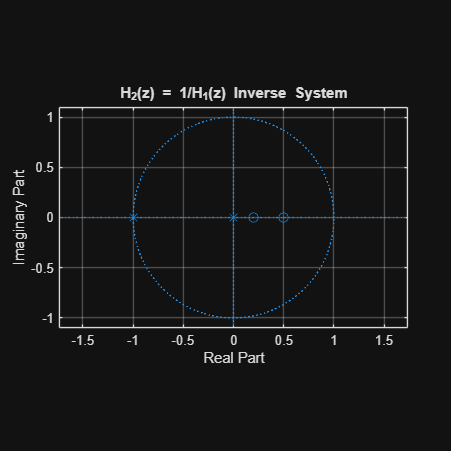


% H2(z) pole-zero plot
figure;
zplane(A, B);
title('H_2(z) = 1/H_1(z) Inverse System');
grid on;
set(gcf, 'Position', [100, 100, 800, 800]);
exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_3_3_H2.png'), 'Resolution', 300);

## EKSAMENSOPGAVE 4 (25%)

%  Filter Realization og Signal Filtering

%% Givne filter koefficienter (fra blokdiagram)
% Numerator (feedforward path): b0, b1, b2, b3
B4 = [0.0102, 0.0305, 0.0305, 0.0102];

% Denominator (feedback path): 1, -a1, -a2, -a3
% NB: Fortegnene i diagrammet!
A4 = [1, -2.0038, 1.4471, -0.3618];

Fs4 = 5000;     % Sampling frequency [Hz]
Ts4 = 1/Fs4;    % Sampling period [s]


## Spørgsmål 4-1: Identificer filter

% (1) Filter form
fprintf('=== Problem 4-1 ===\n\n');

=== Problem 4-1 ===



fprintf('(1) Filter form: Direct Form I\n');

(1) Filter form: Direct Form I


fprintf('    - Separate feedforward and feedback sections\n');

    - Separate feedforward and feedback sections


fprintf('    - Two delay chains\n\n');

    - Two delay chains




% (2) FIR or IIR?
fprintf('(2) Filter type: IIR (Infinite Impulse Response)\n');

(2) Filter type: IIR (Infinite Impulse Response)


fprintf('    Why? Current output y[n] depends on previous outputs\n');

    Why? Current output y[n] depends on previous outputs


fprintf('         (feedback present: y[n-1], y[n-2], y[n-3])\n\n');

         (feedback present: y[n-1], y[n-2], y[n-3])




% (3) Transfer Function H(z)
fprintf('(3) Transfer function H(z):\n');

(3) Transfer function H(z):


H4_sys = tf(B4, A4, Ts4, 'Variable', 'z^-1')


H4_sys =
 
  0.0102 + 0.0305 z^-1 + 0.0305 z^-2 + 0.0102 z^-3
  ------------------------------------------------
     1 - 2.004 z^-1 + 1.447 z^-2 - 0.3618 z^-3
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


## Spørgsmål 4-2: Plot magnitude response

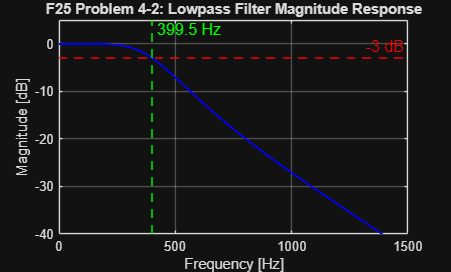

% Frequency vector (0 to Nyquist)
F_vec = linspace(0, Fs4/2, 10000);  % Hz

% Compute frequency response
[H4, F4_resp] = freqz(B4, A4, F_vec, Fs4);

% Magnitude in dB
Mag4_dB = 20*log10(abs(H4));

% Plot
figure;
plot(F4_resp, Mag4_dB, 'b-', 'LineWidth', 1.5);
hold on;
grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('F25 Problem 4-2: Lowpass Filter Magnitude Response');

% Mark -3 dB line
yline(-3, '--r', '-3 dB', 'LineWidth', 1.5, 'FontSize', 12);

% Find -3 dB frequency
idx_3dB = find(Mag4_dB >= -3, 1, 'last');
F_3dB = F4_resp(idx_3dB);

% Mark the found frequency
xline(F_3dB, '--g', sprintf('%.1f Hz', F_3dB), ...
      'LineWidth', 1.5, 'FontSize', 12, 'LabelOrientation', 'horizontal');

xlim([0, 1500]);  % Focus on relevant frequency range
ylim([-40 5]);
hold off;

% Export
exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_4_2_Magnitude.png'), ...
               'Resolution', 300);

% Optional
% Display results
fprintf('Magnitude Response Analysis:\n');

Magnitude Response Analysis:


fprintf('  Measured -3 dB frequency: %.2f Hz\n', F_3dB);

  Measured -3 dB frequency: 399.54 Hz


fprintf('  Specified frequency:      400.00 Hz\n');

  Specified frequency:      400.00 Hz


fprintf('  Difference:               %.2f Hz\n', abs(F_3dB - 400));

  Difference:               0.46 Hz


fprintf('  Relative error:           %.2f%%\n\n', abs(F_3dB - 400)/400 * 100);

  Relative error:           0.12%




if abs(F_3dB - 400) < 10
    fprintf('✓ Filter meets specification (within 10 Hz tolerance)\n\n');
else
    fprintf('⚠ Filter does NOT meet specification\n\n');
end

✓ Filter meets specification (within 10 Hz tolerance)



## Spørgsmål 4-3: Pole-zero analyse

% Find poles and zeros
zeros_H4 = roots(B4);
poles_H4 = roots(A4);

% Display
fprintf('\nZeros:\n');


Zeros:


disp(zeros_H4);

  -0.9951 + 0.0989i
  -0.9951 - 0.0989i
  -1.0000 + 0.0000i



fprintf('Zeros magnitudes: ');

Zeros magnitudes: 

disp(abs(zeros_H4)');

    1.0000    1.0000    1.0000




fprintf('\nPoles:\n');


Poles:


disp(poles_H4);

   0.7063 + 0.3363i
   0.7063 - 0.3363i
   0.5912 + 0.0000i



fprintf('Pole magnitudes: ');

Pole magnitudes: 

disp(abs(poles_H4)');

    0.7823    0.7823    0.5912




% Stability check
fprintf('\n--- Stability ---\n');


--- Stability ---


if all(abs(poles_H4) < 1)
    fprintf('✓ STABLE (all |p| < 1)\n');
else
    fprintf('✗ NOT STABLE\n');
end

✓ STABLE (all |p| < 1)


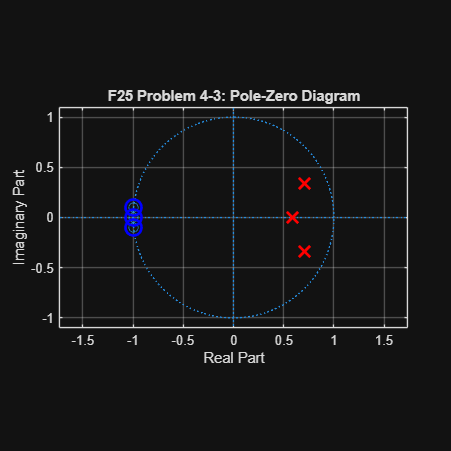


% Plot pole-zero diagram
figure;
zplane(B4, A4);
title('F25 Problem 4-3: Pole-Zero Diagram');
grid on;

%Make plot prettier
hold on;
plot(real(poles_H4), imag(poles_H4), 'rx', 'MarkerSize', 12, 'LineWidth', 2);
plot(real(zeros_H4), imag(zeros_H4), 'bo', 'MarkerSize', 12, 'LineWidth', 2);
hold off;

set(gcf, 'Position', [100, 100, 800, 800]);

exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_4_3_PoleZero.png'), ...
               'Resolution', 300);

## Spørgsmål 4-4: Sampling af analogt signal

% Given analog signal: xa(t) = 5*cos(2π*50*t) + 3*cos(2π*1000*t)
A1 = 5;   F1 = 50;      % First component
A2 = 3;   F2 = 1000;    % Second component
Fs4 = 5000;             % Sampling frequency

% Check aliasing
F_Nyquist = Fs4/2;
fprintf('\n=== Problem 4-4: Aliasing Check ===\n');


=== Problem 4-4: Aliasing Check ===


fprintf('Nyquist frequency: %.0f Hz\n\n', F_Nyquist);

Nyquist frequency: 2500 Hz




fprintf('Component 1: F1 = %.0f Hz\n', F1);

Component 1: F1 = 50 Hz


if F1 < F_Nyquist
    fprintf('  %.0f < %.0f → NO aliasing ✓\n\n', F1, F_Nyquist);
else
    fprintf('  %.0f >= %.0f → ALIASING! ⚠️\n\n', F1, F_Nyquist);
end

  50 < 2500 → NO aliasing ✓




fprintf('Component 2: F2 = %.0f Hz\n', F2);

Component 2: F2 = 1000 Hz


if F2 < F_Nyquist
    fprintf('  %.0f < %.0f → NO aliasing ✓\n\n', F2, F_Nyquist);
else
    fprintf('  %.0f >= %.0f → ALIASING! ⚠️\n\n', F2, F_Nyquist);
end

  1000 < 2500 → NO aliasing ✓



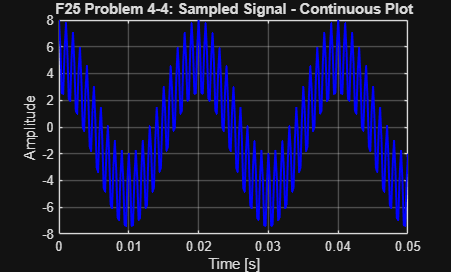


% Sample the signal (0 to 0.05 seconds)
t4 = 0:1/Fs4:0.05;
x4_sampled = A1*cos(2*pi*F1*t4) + A2*cos(2*pi*F2*t4);

% Plot sampled signal - CONTINUOUS PLOT (more illustrative)
figure;
plot(t4, x4_sampled, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('Amplitude');
title('F25 Problem 4-4: Sampled Signal - Continuous Plot');
xlim([0 0.05]);

exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_4_4_Sampled_Plot.png'), ...
               'Resolution', 300);

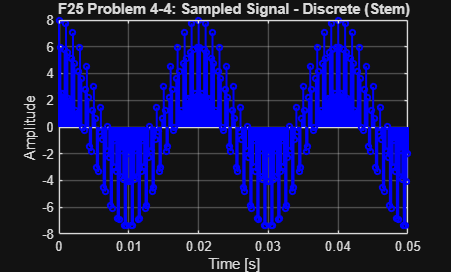


% Plot sampled signal - STEM PLOT (shows discrete nature)
figure;
stem(t4, x4_sampled, 'b', 'LineWidth', 1.5, 'MarkerSize', 4);
grid on;
xlabel('Time [s]');
ylabel('Amplitude');
title('F25 Problem 4-4: Sampled Signal - Discrete (Stem)');
xlim([0 0.05]);

exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_4_4_Sampled_Stem.png'), ...
               'Resolution', 300);

## Spørgsmål 4-5: Filter signalet

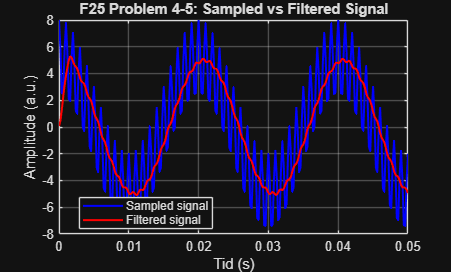

% Filter the signal using the lowpass filter from 4-1
y4_filtered = filter(B4, A4, x4_sampled);

% OVERLAY PLOT: Both signals on same axes (like student solution)
figure;
plot(t4, x4_sampled, 'b', 'LineWidth', 1.5);
hold on;
plot(t4, y4_filtered, 'r', 'LineWidth', 1.5);
hold off;

grid on;
xlabel('Tid (s)');
ylabel('Amplitude (a.u.)');
title('F25 Problem 4-5: Sampled vs Filtered Signal');
legend('Sampled signal', 'Filtered signal', 'Location', 'best');
xlim([0 0.05]);

exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_4_5_Overlay.png'), ...
               'Resolution', 300);

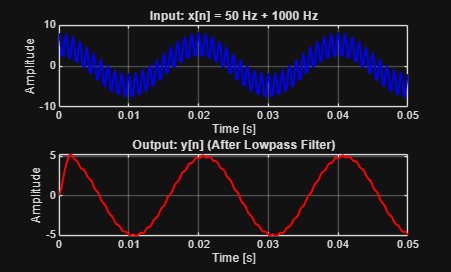


% OPTIONAL: Still create separate subplots if you want both views
figure;
subplot(2,1,1);
plot(t4, x4_sampled, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('Amplitude');
title('Input: x[n] = 50 Hz + 1000 Hz');
xlim([0 0.05]);

subplot(2,1,2);
plot(t4, y4_filtered, 'r', 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('Amplitude');
title('Output: y[n] (After Lowpass Filter)');
xlim([0 0.05]);

exportgraphics(gcf, fullfile(imgDir, 'DSP_Exam_F25_4_5_Separate.png'), ...
               'Resolution', 300);


% Analysis
fprintf('\nFilter effect:\n');


Filter effect:


fprintf('  - 50 Hz (in passband):   PASSES ✓\n');

  - 50 Hz (in passband):   PASSES ✓


fprintf('  - 1000 Hz (in stopband): ATTENUATED ✓\n');

  - 1000 Hz (in stopband): ATTENUATED ✓


fprintf('  - Result: Smooth 50 Hz sine wave\n\n');

  - Result: Smooth 50 Hz sine wave



## APPENDIX: Butterworth Lowpass Prototype (ε = 1, 3 dB)

%{
Order n | Denominator polynomial
--------|------------------------------------------
   1    | s + 1
   2    | s^2 + 1.4142s + 1
   3    | s^3 + 2s^2 + 2s + 1
   4    | s^4 + 2.6131s^3 + 3.4142s^2 + 2.6131s + 1
   5    | s^5 + 3.2361s^4 + 5.2361s^3 + 5.2361s^2 + 3.2361s + 1
   6    | s^6 + 3.8637s^5 + 7.4641s^4 + 9.1416s^3 + 7.4641s^2 + 3.8637s + 1

All have numerator = 1
%}

% Prototype polynomials for quick reference:
proto_den{1} = [1, 1];
proto_den{2} = [1, 1.4142, 1];
proto_den{3} = [1, 2, 2, 1];
proto_den{4} = [1, 2.6131, 3.4142, 2.6131, 1];
proto_den{5} = [1, 3.2361, 5.2361, 5.2361, 3.2361, 1];
proto_den{6} = [1, 3.8637, 7.4641, 9.1416, 7.4641, 3.8637, 1];